% Define the list of files
file_list = {'sim_data\pi_load0p3', 'sim_data\mpc_load0p3','sim_data\rl_load0p3'};

time_data = cell(1, length(file_list));
speedfb_data = cell(1, length(file_list));
speedref_data = cell(1, length(file_list));

% Process each file
for i = 1:length(file_list)
    % Read data from the file
    [xls_data, xls_txt] = xlsread(file_list{i});
    
    % Store 'time', 'Speed_fb', 'Speed_Ref' columns in cell arrays
    time_data{i} = xls_data(:, strcmp(xls_txt(1,:), 'time'));
    speedfb_data{i} = xls_data(:, strcmp(xls_txt(1,:), 'Speed_fb'));
    speedref_data{i} = xls_data(:, strcmp(xls_txt(1,:), 'Speed_Ref'));
end

% Calculate system metrics for each dataset
step_input = cellfun(@max, speedref_data);
steady_state_value = cellfun(@(x) mean(x(end-10:end)), speedfb_data);
steady_state_error = abs(step_input - steady_state_value);

overshoot = zeros(1, length(file_list));
rise_time = zeros(1, length(file_list));
settling_time = zeros(1, length(file_list));

tolerance = 0.02;

for i = 1:length(file_list)
    % Calculate overshoot
    [peak_value, ~] = max(speedfb_data{i});
    overshoot(i) = ((peak_value - steady_state_value(i)) / steady_state_value(i)) * 100;
    
    % Calculate rise time (10% to 90% of steady state value)
    rise_start = steady_state_value(i) * 0.1;
    rise_end = steady_state_value(i) * 0.9;
    rise_start_index = find(speedfb_data{i} >= rise_start, 1, 'first');
    rise_end_index = find(speedfb_data{i} >= rise_end, 1, 'first');
    rise_time(i) = time_data{i}(rise_end_index) - time_data{i}(rise_start_index);
    
    % Calculate settling time (within tolerance of steady state value)
    upper_bound = steady_state_value(i) * (1 + tolerance);
    lower_bound = steady_state_value(i) * (1 - tolerance);
    out_of_bounds_indices = find((speedfb_data{i} > upper_bound) | (speedfb_data{i} < lower_bound));
    settling_time(i) = time_data{i}(out_of_bounds_indices(end));
end

legend_labels = {'PI Load 0.3', 'MPC Load 0.3', 'RL Load 0.3'};

% Display results for each dataset
for i = 1:length(file_list)    
    fprintf('=== %s ===', legend_labels{i});
    fprintf('Overshoot: %.2f%%\n', overshoot(i));
    fprintf('Rise Time: %.4f seconds\n', rise_time(i));
    fprintf('Settling Time: %.4f seconds\n', settling_time(i) - 5);
    fprintf('Steady-State Error: %.4f\n', steady_state_error(i));
    fprintf('\n');
end

=== PI Load 0.3 ===

Overshoot: 33.90%


Rise Time: 0.0340 seconds


Settling Time: 0.2720 seconds


Steady-State Error: 0.0001


=== MPC Load 0.3 ===

Overshoot: 30.29%


Rise Time: 0.0580 seconds


Settling Time: 0.3700 seconds


Steady-State Error: 0.0000


=== RL Load 0.3 ===

Overshoot: 0.01%


Rise Time: 0.0920 seconds


Settling Time: 0.3800 seconds


Steady-State Error: 0.0000


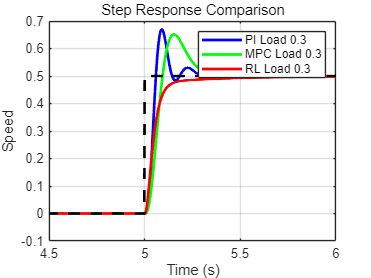


% Plot response curves
figure;
colors = {'b-', 'g-', 'r-'};
for i = 1:length(file_list)
    plot(time_data{i}, speedfb_data{i}, colors{i}, 'LineWidth', 2);
    hold on;
end
plot(time_data{1}, speedref_data{1}, 'k--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed');

legend(legend_labels);
title('Step Response Comparison');
grid on;
xlim([4.5, 6]);